# Exam B Question 2

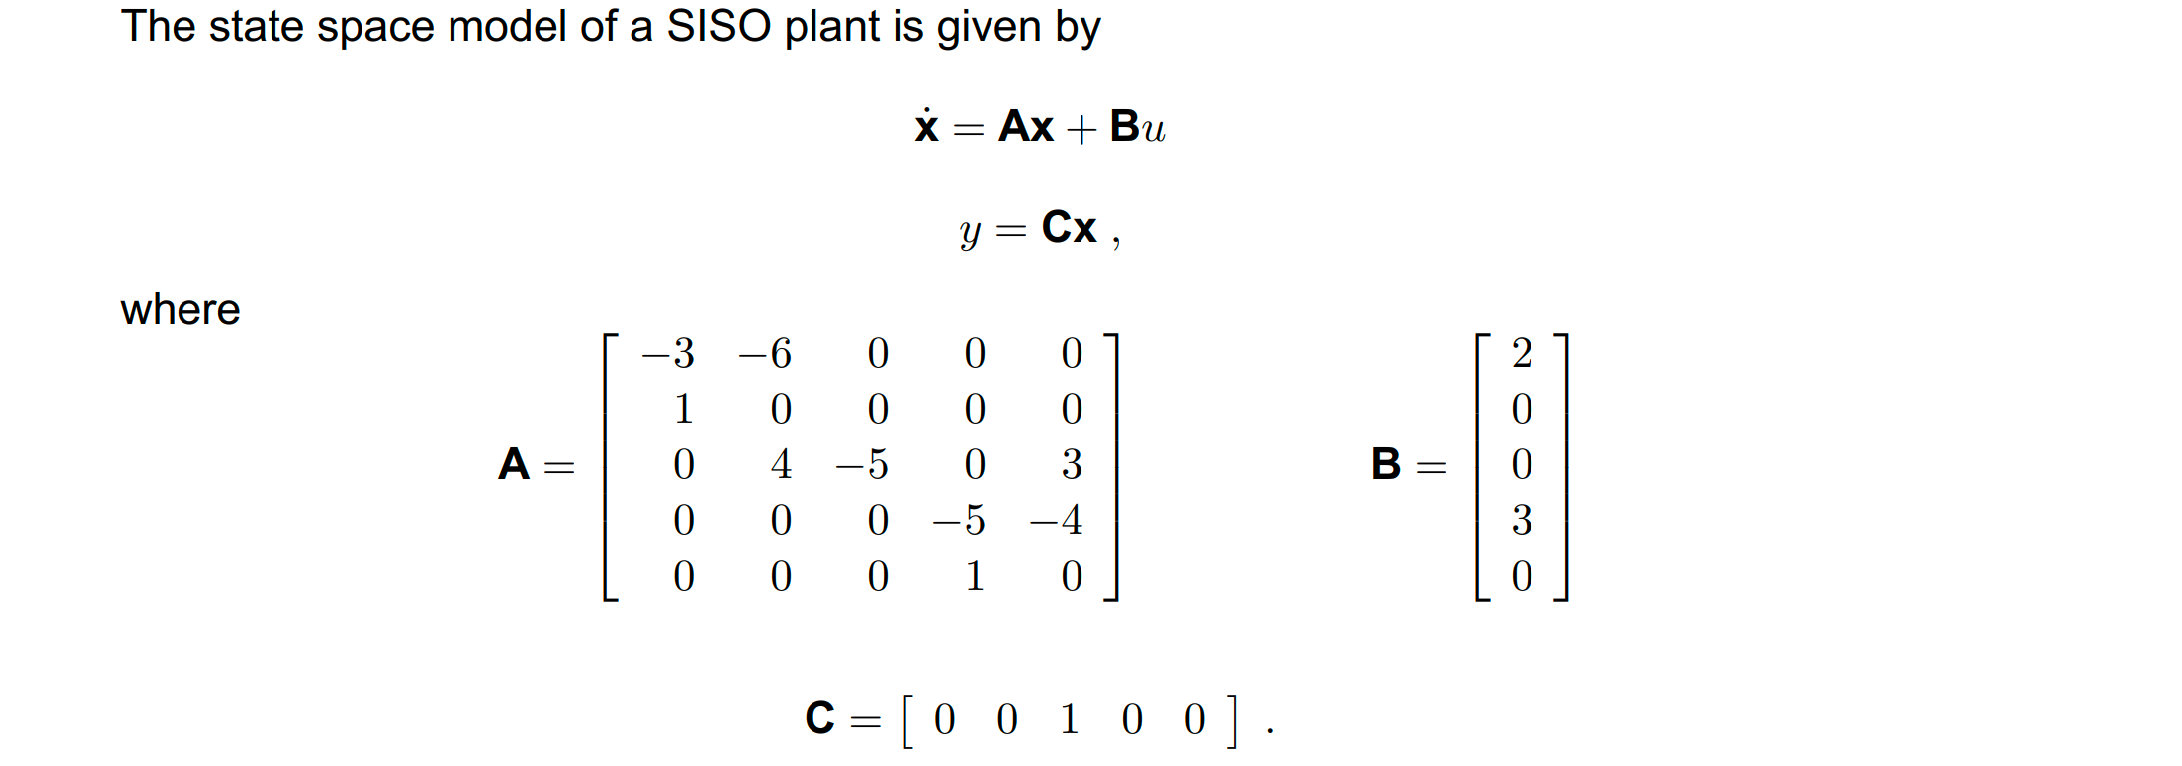

A = [-3, -6, 0, 0, 0;
     1 ,  0, 0, 0, 0;
     0 ,  4,-5, 0, 3;
     0,   0, 0,-5,-4;
     0 ,  0, 0, 1, 0];

B = [2;0;0;3;0];

C = [0,0,1,0,0];
D = 0;

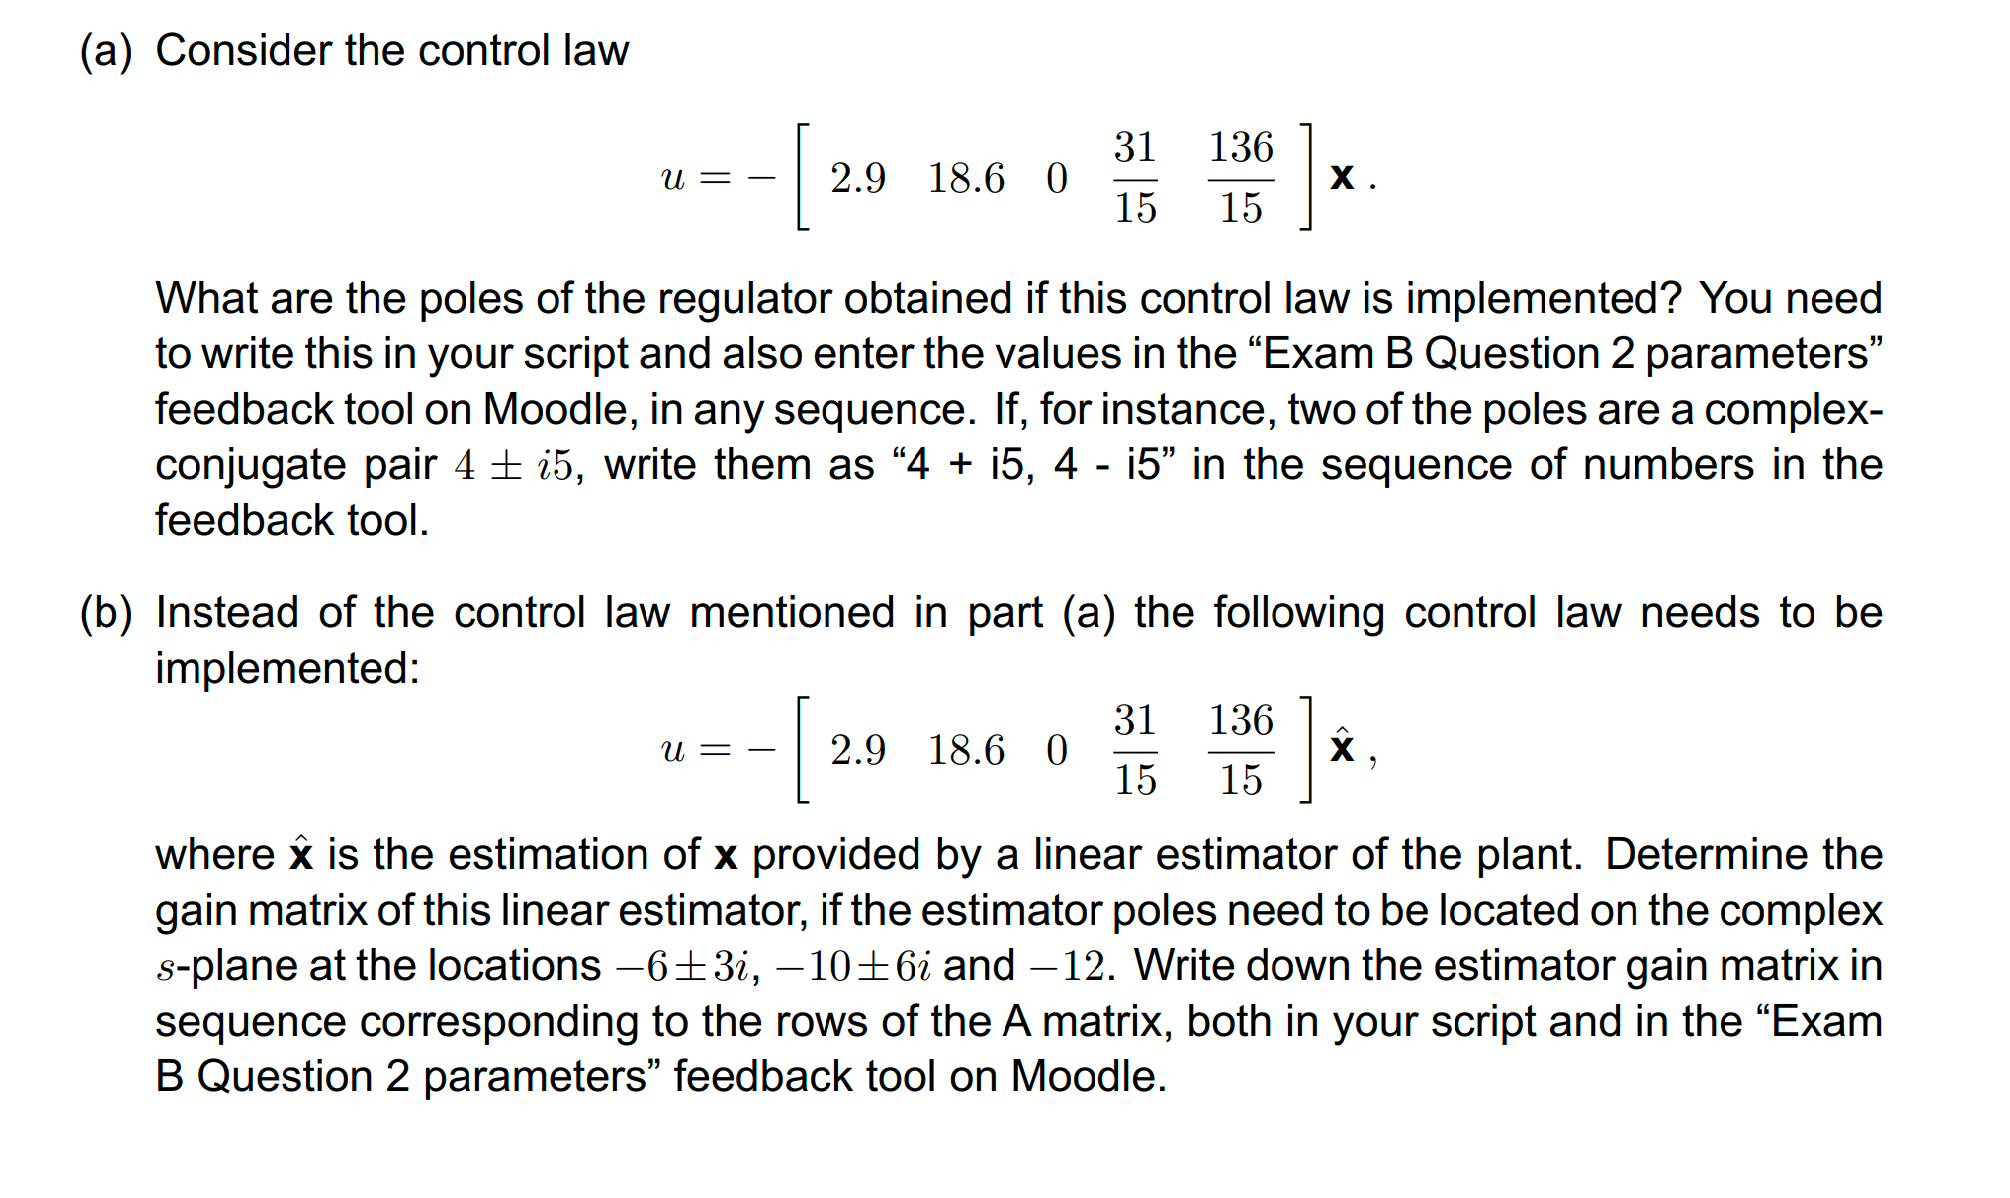

## (a)


$$\begin{array}{l}
\dot{\;x} =\mathrm{Ax}+\mathrm{Bu}\\
u=-\mathrm{Kx}\\
\dot{x} =\mathrm{Ax}-\mathrm{BKx}=\left(A-\mathrm{BK}\right)x
\end{array}$$


To find the poles, we need to calculate the eignvalue of matrix $A-\mathrm{BK}$

K = -[2.9 18.6 0 31/15 136/15]

K =    -2.9000  -18.6000         0   -2.0667   -9.0667


poles = eig(A+B*K)

poles =    -5.0000
   -8.0000
   -7.0000
   -3.0000
   -2.0000


## (b)

Adding the estimator 


$$\begin{array}{l}
u=-K\hat{x} \\
\mathrm{now}\;\dot{x} =\mathrm{Ax}-\mathrm{BK}\hat{x\;} \\
\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\hat{x} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & -\mathrm{BK}\\
\mathrm{LC} & A-\mathrm{BK}-\mathrm{LC}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack 
\end{array}$$


est_poles = [-6+j*3, -6-j*3, -10+6*j, -10-6*j, -12];
L = acker(A', C', est_poles)'

L = 1.0e+03 *

    1.3385
   -0.7262
    0.0310
   -0.8827
    1.1323


Acl_b = [A,       -B*K;
         L*C,   A-L*C-B*K];
pole_b = eig(Acl_b);
fprintf('the poles are: \n');

the poles are: 


display(pole_b);

pole_b =   12.7347 + 0.0000i
 -10.0000 + 6.0000i
 -10.0000 - 6.0000i
 -12.0000 + 0.0000i
  -6.0000 + 3.0000i
  -6.0000 - 3.0000i
  -2.1762 + 0.6517i
  -2.1762 - 0.6517i
  -5.0000 + 0.0000i
  -4.3823 + 0.0000i
